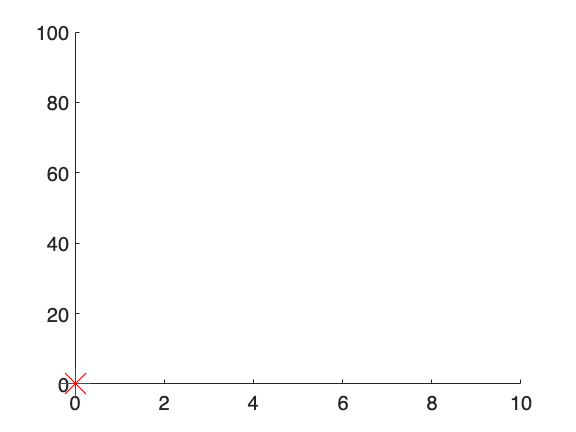

close all; clear all; clc;

m = 50; % [kg]
a = 30; % [km/h^2]

dt = 1; % [sec]
t = 0:dt:100;

v(1) = 0; % [km/h]

%1. Force = measurement x acceleration

fig = figure(1);

ax = axes('parent', fig, 'xlim', [0 10], 'ylim', [0 100]);
li = line('parent',ax,'xdata',[0],'ydata',[0],...
    'marker','*','markersize',15,'markeredgecolor',[1 0 0]);

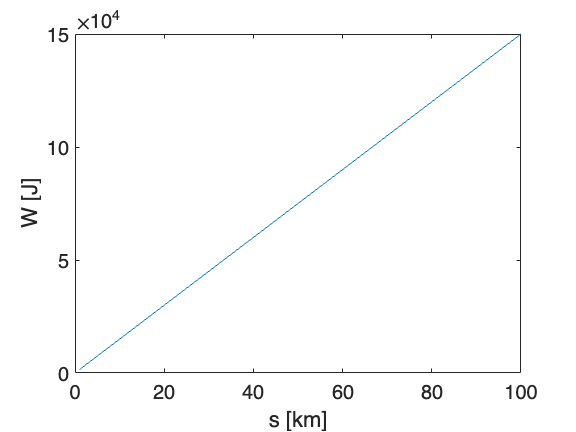


F = m*a;

ds = 1;
s = 1:ds:100;

for i = 1:length(s)
    W(i) = F*s(i);
end

figure()
plot(s, W)
xlabel('s [km]')
ylabel('W [J]')


for i = 1:length(t)
    v(i+1) = a*dt + v(i);
end

figure()
plot(t, v)

다음 사용 중 오류가 발생함: plot
벡터들의 길이는 같아야 합니다.

xlabel('t [sec]')
ylabel('v [km/h]')
